## MotorCAD

VisualizeFluxSurfaceTeslaSPlaid

%figure
hold on
figure(1)
surf(MotorCADFEA.Id_Peak,MotorCADFEA.Iq_Peak,MotorCADFEA.Flux_Linkage_D);
%figure
figure(2)
hold on
surf( MotorCADFEA.Id_Peak,MotorCADFEA.Iq_Peak,MotorCADFEA.Flux_Linkage_Q);
close all

% check devMBCTeslaSPlaidFromDankai

## Maxwell

ee_ece_table

fluxD1D=fluxD(:,:,1)
fluxD1DHalft=fluxD1D(1:10,11:21)
fluxQ1D=fluxQ(:,:,1)
fluxQ1DHalft=fluxQ1D(1:10,11:21)
a=fluxD1DHalft'
%% TransPose 
mesh(idVec(1:10),iqVec(11:21),fluxD1DHalft')
scatter3(idVec(1:10),iqVec(11),a(1,:))
xlabel('id')
ylabel('iq')


size(idVec(1:11))
size(iqVec(11:21))
size(fluxQ1DHalft)
mesh(idVec(1:11),iqVec(11:21),fluxQ1DHalft')
xlabel('id')
ylabel('iq')
% surf(fluxD1DHalft)
% surf(fluxQ1DHalft)

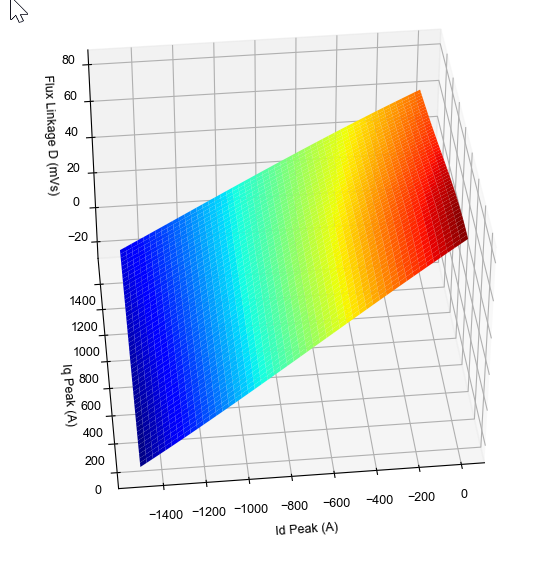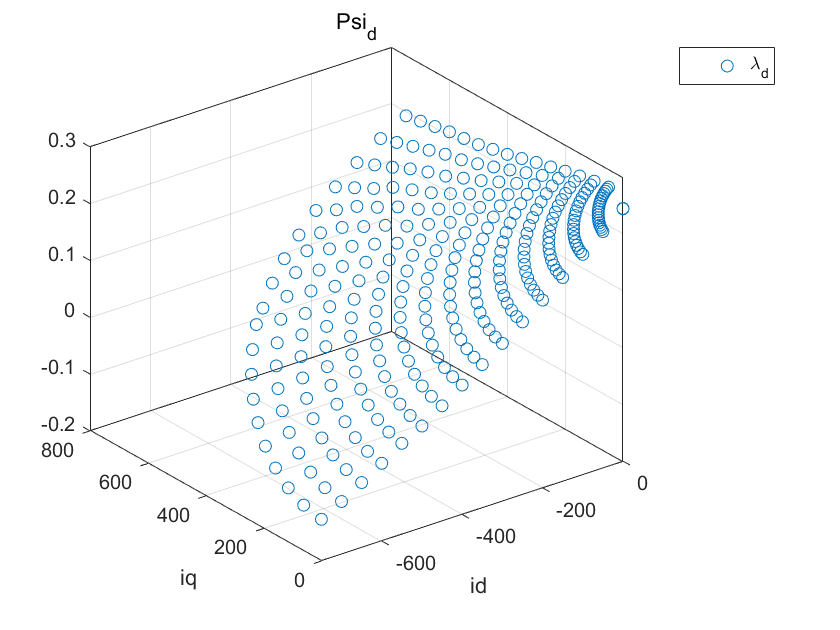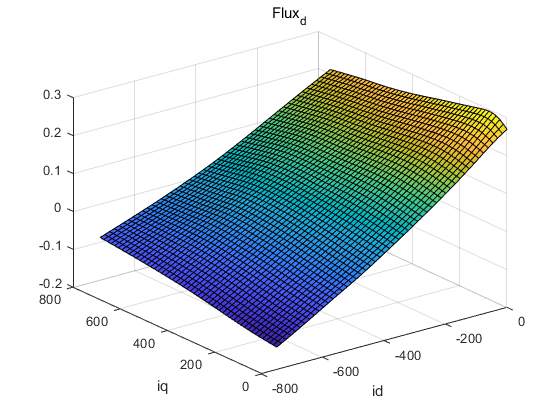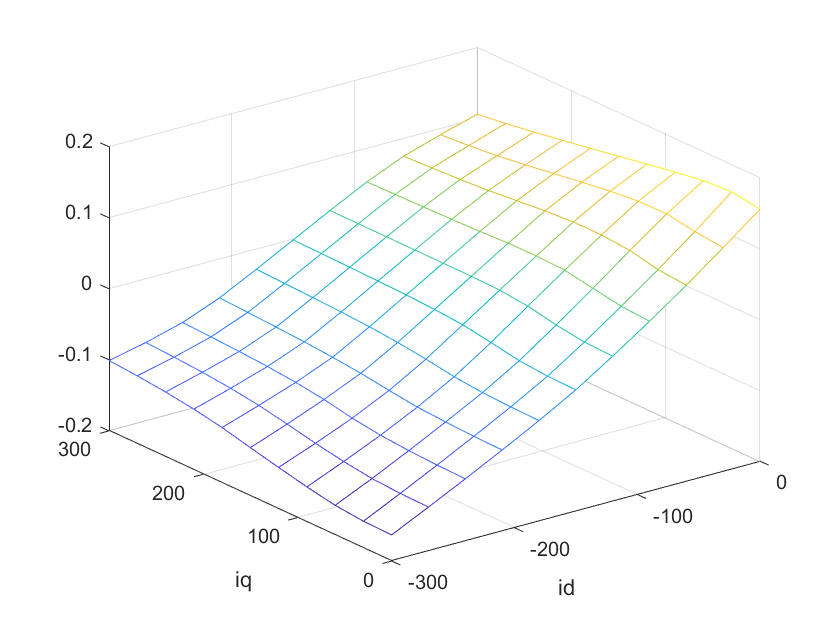

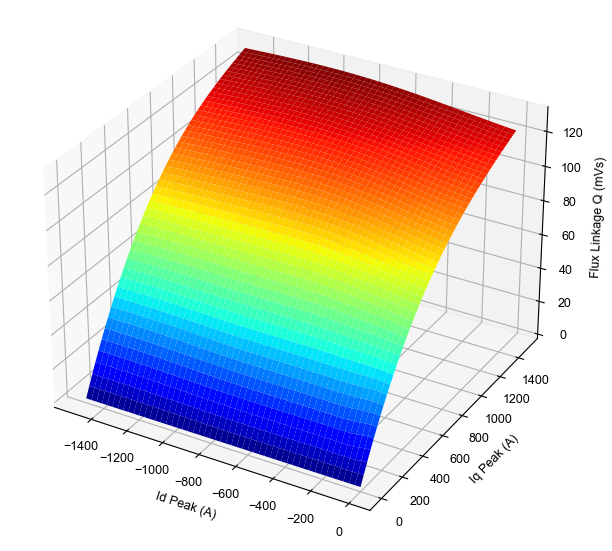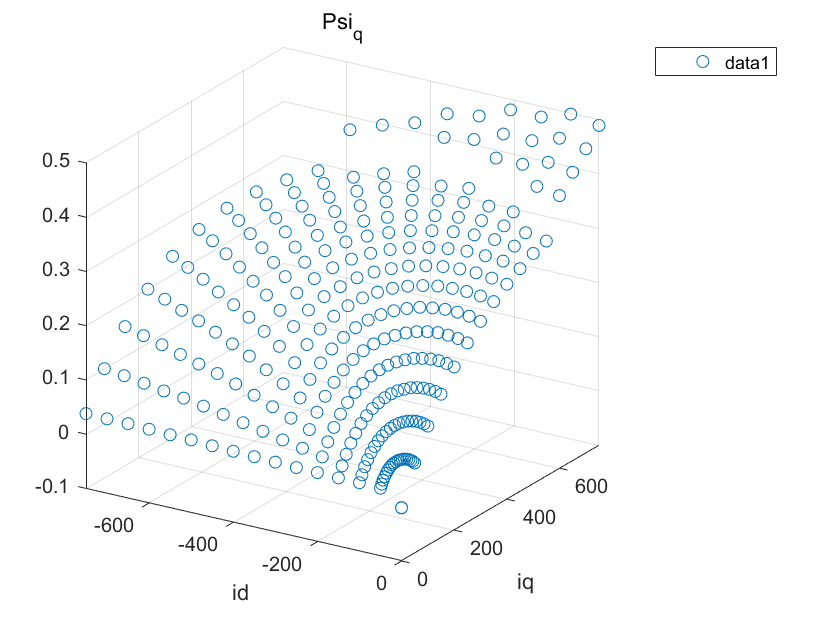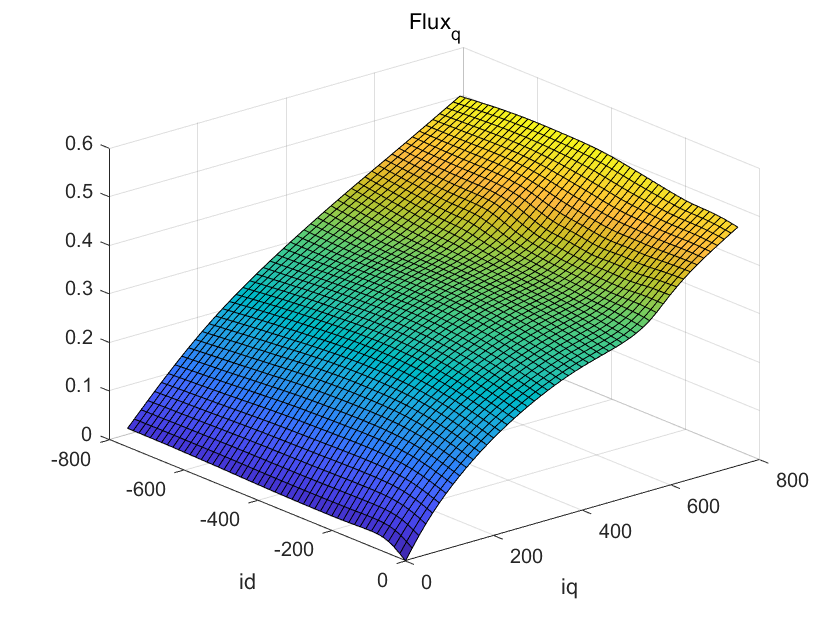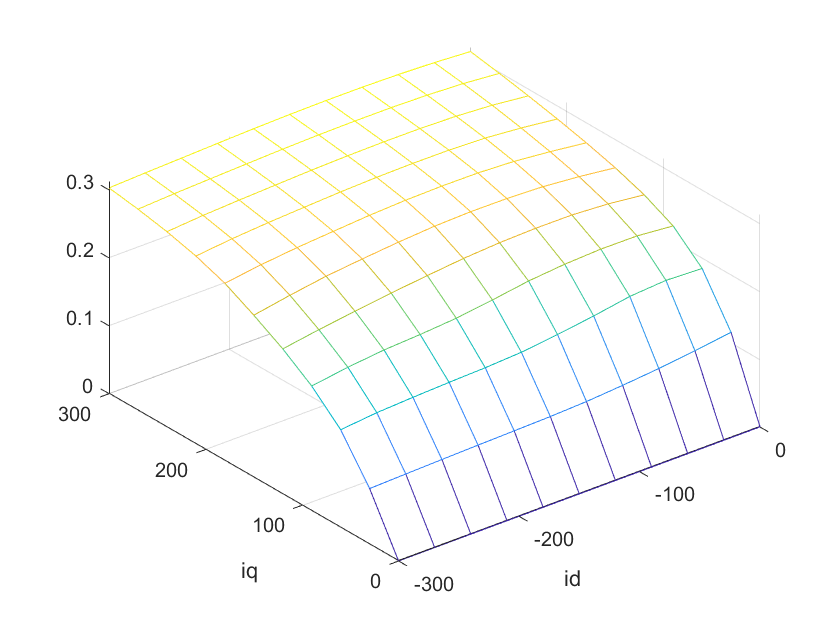

## DataDqMap